# Growth Kinetics Analaysis

clear;
clc;

## Wild Type

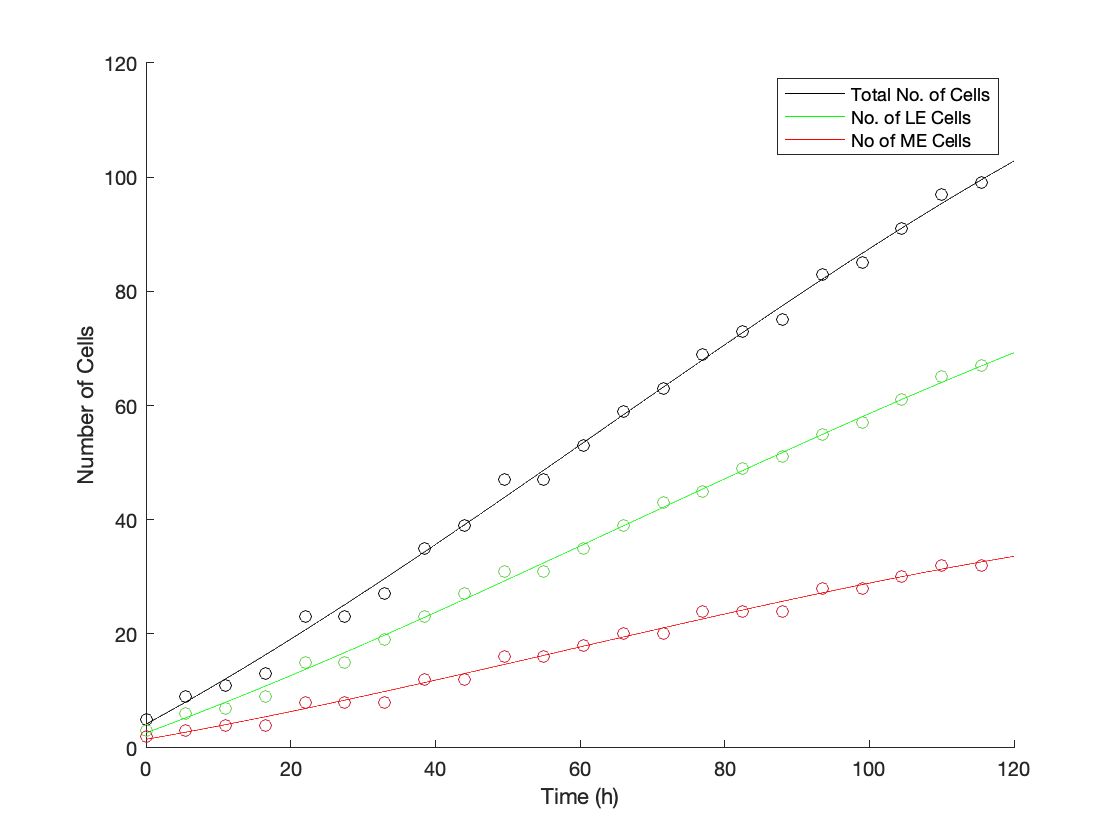

WT = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/results_from_time_0/location.dat";
[numberofcells, yLE, yME, yTotal, ME, LE] = TimeVsNoCells(WT);

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [69 34]

  Show all properties


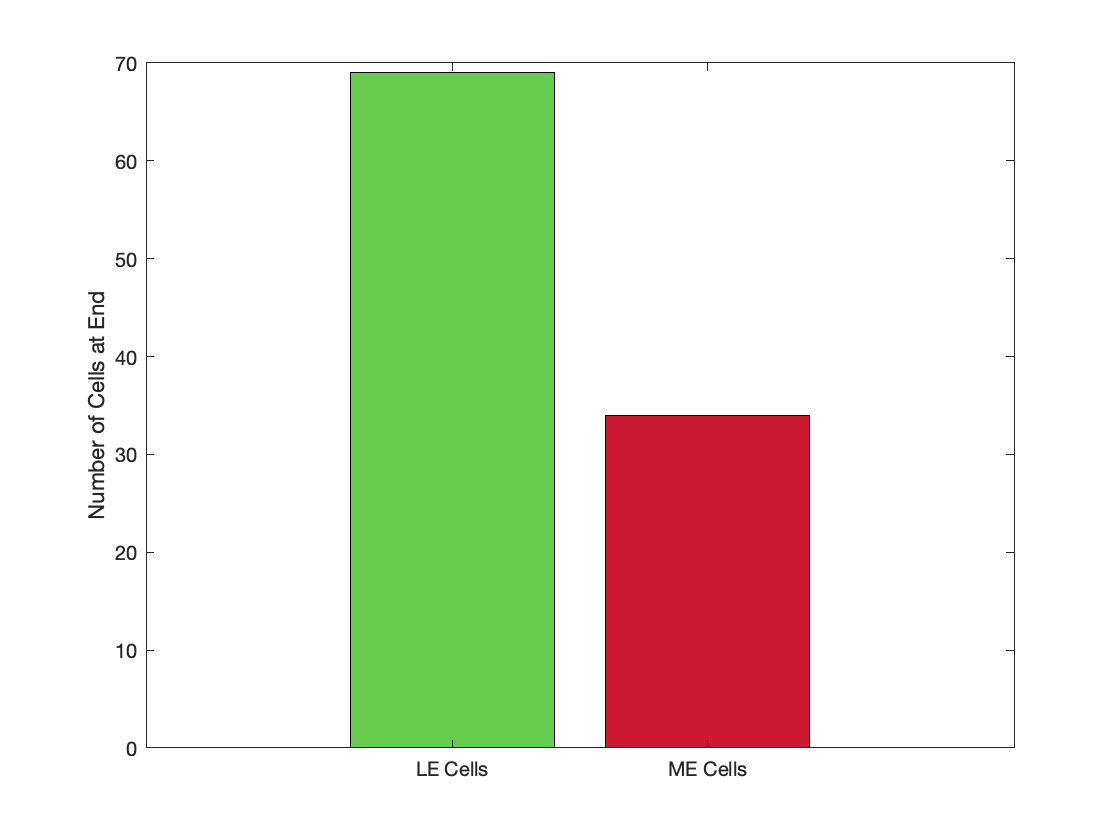

Error using matlab.io.ImportOptions/readmatrix (line 679)
Unable to find or open '/Users/Priya/testoutput/TestMammaryMonolayerB1MEKO/results_from_time_0/location.dat'. Check the path and filename or file permissions.

Error in importfile_displacement (line 46)
displacement = readmatrix(filename, opts);

Error in <a hr

figure
hold on

scatter(x(1:55:end), yTotal(1:55:end), 'k')
pWT = polyfit(x,yTotal,3);
fWT = polyval(pWT,x);
total = plot(x,fWT, 'k');

scatter(x(1:55:end), yLE(1:55:end), [], LE)
pLE = polyfit(x,yLE,3);
fLE = polyval(pLE,x);
LE = plot(x,fLE, 'g');

scatter(x(1:55:end), yME(1:55:end), [], ME)
pME = polyfit(x,yME,3);
fME = polyval(pME,x);
ME = plot(x,fME, 'r');

hold off

ylabel ('Number of Cells')
xlabel('Time (h)')
legend([total, LE, ME],'Total No. of Cells', 'No. of LE Cells', 'No of ME Cells')

folder = '~/Desktop/';
exportgraphics(gca, 'FigureCellsvsTime.pdf');
movefile('FigureCellsvsTime.pdf', folder);

% [WTnumberofcells] = CellCount_Graph(WT);